clear;clc;close all;

R = 10;
L = 0.01;
C = 1e-6;
f = logspace(0, 6, 2000);

[Z, mag, phase] = calc_impedance(R, L, C, f); %通过这个方式直接得到Z, mag, phase。就不用再写运算式了

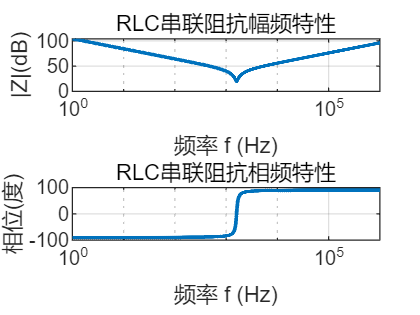

figure;
subplot(2,1,1);
semilogx(f, 20*log10(mag), 'LineWidth',1.5);
grid on
xlabel('频率 f (Hz)')
ylabel('|Z|(dB)')
title('RLC串联阻抗幅频特性')

subplot(2,1,2);
semilogx(f, phase, 'LineWidth',1.5);
grid on
xlabel('频率 f (Hz)')
ylabel('相位(度)')
title('RLC串联阻抗相频特性')